# ECG Wavelet Filtering Test Program

This program tests the effectiveness of the ecgFilter function It displays a comparison of a signal before and after filtering using data from the MIT-BIH Arrhythmia Database

clear all;
close all;
clc;

% Specify the database path - update this to your local path
PATH = 'D:\Download\Google Drive\2025 Semester 1\ENG 7002A Masters Eng Res Project\ENG 7002 Master Project Code\MIT-BIH'; 
SAMPLES2READ = 650000;      % Number of samples to read
% Name_whole = 106;         % List of record IDs

% Select a record for testing (e.g., 100)
recordName = '221';
fprintf('Processing record %s ...\n', recordName);

Processing record 221 ...



% Load ECG data using the loadECGData function
% This retrieves signal data and annotation information
[M, ATRTIMED, ANNOTD, TIME] = loadECGdata(recordName, PATH, SAMPLES2READ);

% 获取注释中的R波位置
% R_TIME = ATRTIMED(ANNOTD == 1 | ANNOTD == 2 | ANNOTD == 3 | ANNOTD == 5 | ANNOTD == 8 | ANNOTD == 9);
% ann = ANNOTD(ANNOTD == 1 | ANNOTD == 2 | ANNOTD == 3 | ANNOTD == 5 | ANNOTD == 8 | ANNOTD == 9);
R_TIME = ATRTIMED(ANNOTD == 5);
ann = ANNOTD(ANNOTD == 5);

% Set sampling frequency
fs = 360;  % Standard sampling frequency for MIT-BIH Arrhythmia Database

% Select the first 5 seconds of data for visualization
seconds_to_show = 10;
samples_to_show = seconds_to_show * fs;

% Extract data for the specified time window
ecg_raw = M(1:samples_to_show, 1);

% Apply ECG filtering using the ecgFilter function
fprintf('Applying filtering...\n');

Applying filtering...


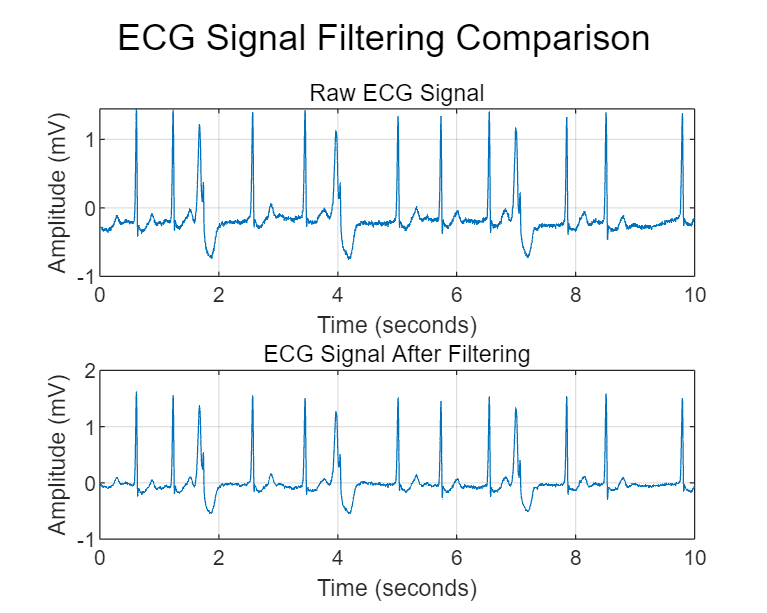

ecg_filtered = ecgFilter(ecg_raw, fs);

% Create time vector for plotting (missing in original code)
t = (0:samples_to_show-1) / fs;

% Plot comparison between raw and filtered signals
figure('Position', [100, 100, 1000, 800]);

% Raw signal plot
subplot(2, 1, 1);
plot(t, ecg_raw);
title('Raw ECG Signal');
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
grid on;
xlim([0, seconds_to_show]);

% Filtered signal plot
subplot(2, 1, 2);
plot(t, ecg_filtered);
title('ECG Signal After Filtering');
xlabel('Time (seconds)');
ylabel('Amplitude (mV)');
grid on;
xlim([0, seconds_to_show]);

% Adjust figure layout and add super title
sgtitle('ECG Signal Filtering Comparison');

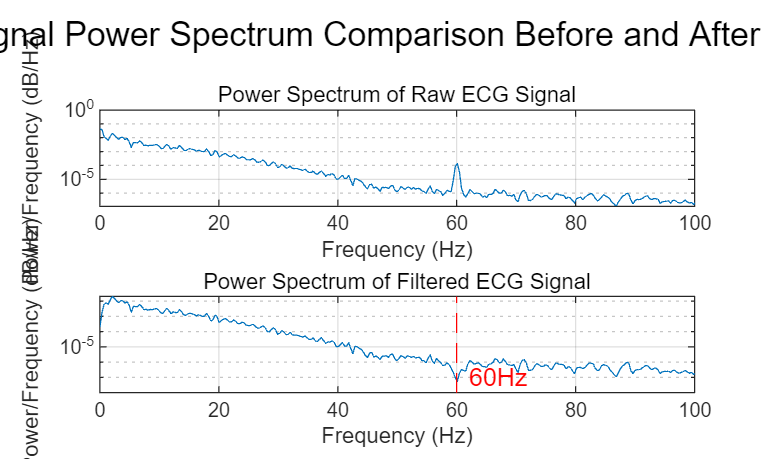


% Add spectral analysis (optional)
figure('Position', [200, 200, 1000, 600]);

% Calculate and plot power spectrum of raw signal
subplot(2, 1, 1);
[pxx_noisy, f_noisy] = pwelch(ecg_raw, [], [], [], fs);
semilogy(f_noisy, pxx_noisy);
title('Power Spectrum of Raw ECG Signal');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
grid on;
xlim([0, 100]);  % Only display 0-100Hz range

% Calculate and plot power spectrum of filtered signal
subplot(2, 1, 2);
[pxx_filtered, f_filtered] = pwelch(ecg_filtered, [], [], [], fs);
semilogy(f_filtered, pxx_filtered);
title('Power Spectrum of Filtered ECG Signal');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
grid on;
xlim([0, 100]);  % Only display 0-100Hz range

% Add marker line showing 60Hz power line frequency
hold on;
plot([60, 60], get(gca, 'YLim'), 'r--');
text(62, min(get(gca, 'YLim'))*10, '60Hz', 'Color', 'r');
hold off;

sgtitle('ECG Signal Power Spectrum Comparison Before and After Filtering');